# Finite Impulse Response (FIR) Filtering

- firls [https://www.mathworks.com/help/signal/ref/firls.html](https://www.mathworks.com/help/signal/ref/firls.html) 

## Generate a kernel

sample_rate = 1024;
nyquist = sample_rate/2; % see nyquist theorem
band_pass = [20 45]; %the desired frequencies
transition = .1; %transition zone of filter
order = 5; % play with a value between 1 and 20 for example
order = round(5*sample_rate/band_pass(1));
kernel_y = [0 0 1 1 0 0];
kernel_x = [0 band_pass(1)-band_pass(1)*transition band_pass(1) band_pass(2) band_pass(2)+band_pass(2)*transition nyquist];
freqs = kernel_x / nyquist;
kernel = firls(order, freqs, kernel_y);
kernel_powers = abs(fft(kernel)).^2;
hz_vals = linspace(0, nyquist, floor(length(kernel)/2)+1);
kernel_powers = kernel_powers(1:length(hz_vals));

## Plot the kernel

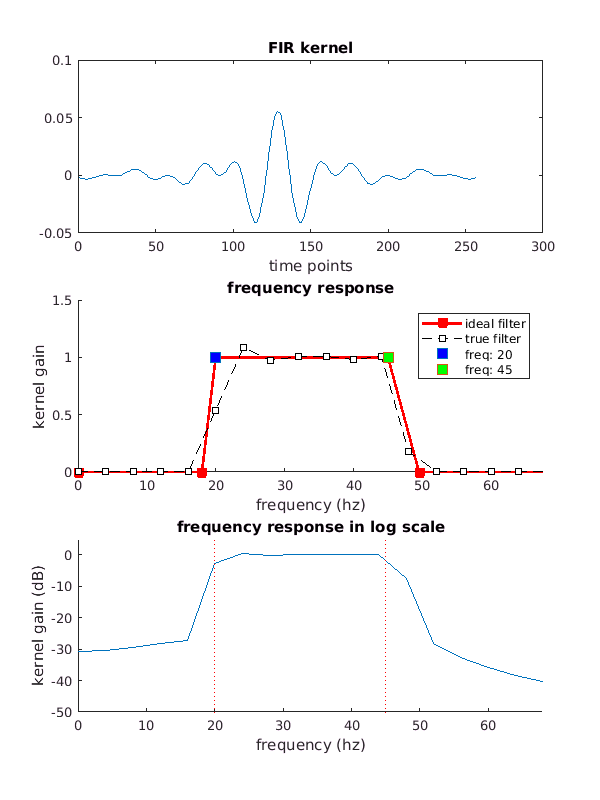

f1 = figure(1); clf;
f1.Position = [0 0 600 800];
subplot(311);
plot(kernel);
xlabel("time points");
title("FIR kernel");

subplot(312);
hold on;
plot(kernel_x, kernel_y, 'rs-', 'linew', 2, 'markersize', 8, 'markerfacecolor', 'r');
plot(hz_vals, kernel_powers, 'ks--', 'markerfacecolor', 'w');
plot(band_pass(1), 1, 's', 'markerfacecolor', 'b', 'markersize', 10);
plot(band_pass(2), 1, 's', 'markerfacecolor', 'g', 'markersize', 10);
xlim([0 kernel_x(5)+kernel_x(2)]); %for centering
ylim([0 1.5]);
title("frequency response");
xlabel("frequency (hz)");
ylabel("kernel gain");
legend(["ideal filter", "true filter", "freq: " + num2str(band_pass(1)), "freq: " + num2str(band_pass(2))]);
hold off;

subplot(313);
hold on;
plot(hz_vals, 10*log10(kernel_powers));
plot([1 1]*band_pass(1), get(gca, 'ylim'), 'r:');
plot([1 1]*band_pass(2), get(gca, 'ylim'), 'r:');
xlim([0 68]);
ylim([-50 5]);
title("frequency response in log scale");
xlabel("frequency (hz)");
ylabel("kernel gain (dB)");




%